# **SISTEMAS DE CONTROL II                              **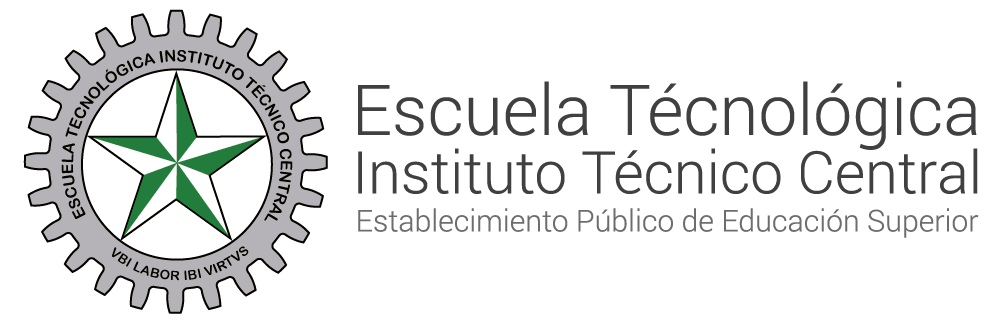

# **Escalón unitario y rampa **

#### Autor ING. Jheyson Fabian Villavisan Buitrago MS.c

#### Coautor: Yenny Michel Wilches Zarate

**Objetivo:** Desarrollar un documento técnico en MATLAB que permita analizar y comprender la representación matemática y simulación de las señales de escalón unitario y rampa en sistemas de control digital, incluyendo su definición, transformadas (Laplace y Z), derivación matemática, y la respuesta de un sistema digital a estas señales.

**Contenido.**

- **Definiciones **de los sistemas en el tiempo continuo y en el tiempo discreto.

- **Definiciones **del escalón unitario y la rampa en el tiempo.

- **Derivación matemática paso a paso** de sus transformadas (Laplace y Z).

- **Simulación en MATLAB** de las señales y su efecto en un sistema digital, con código y gráficos.

- **Interpretación de resultados** para el análisis de sistemas de control.

# **Sistema en tiempo continuo.**

**Definición: **Un sistema en tiempo continuo procesa señales definidas para todos los instantes de tiempo $t$ dentro de un intervalo continuo $\left(t\in \mathbb{R}\right)$. Las señales y las respuestas del sistema varían de manera continua con el tiempo.

# **Sistema en tiempo discreto.**

**Definición: **Un sistema en tiempo discreto procesa señales definidas solo en instantes específicos de tiempo $t=kT_s$, donde $T_s$ es el período de muestreo y $k$ es un entero $\left(k\in \mathbb{Z}\right)$. La señal se representa como una secuencia de valores.

- **Tiempo continuo:** Trabaja con señales y respuestas continuas. Es el modelo teórico exacto.

- **Tiempo discreto:** Trabaja con señales muestreadas. Es la versión aproximada pero aplicable en sistemas digitales reales.

# **Escalón unitario.**

- **Definición:**

El escalón unitario, denotado como $u\left(t\right)$, es una función definida como:


$$u\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \textrm{si}\;t<0\\
1 & \textrm{si}\;t\ge 0
\end{array}\right.$$


- **Demostración matemática:**

Para un sistema continuo,** la transformada de Laplace** de una función $f\left(t\right)$ está dada por:


$$F\left(s\right)=$$

$$\int_0^{\infty } f\left(t\right)e^{-\textrm{st}} \textrm{dt}$$


Aplicando esto al escalón unitario:


$$U\left(s\right)=$$

$$\int_0^{\infty } 1\cdot e^{-\textrm{st}} \textrm{dt}$$


Resolviendo la integral:


$$U\left(s\right)=\left\lbrack -\frac{1}{s}e^{-\textrm{st}} \right\rbrack$$


- Cuando $t\longrightarrow \infty ,e^{-\textrm{st}} \longrightarrow 0\;\textrm{si}\;s>0$

- Cuando $t=0,e^{-\textrm{st}} =1$

Por lo tanto: 


$$\mathit{\mathbf{U}}\left(\mathit{\mathbf{s}}\right)=\frac{1}{\mathit{\mathbf{s}}}$$


En sistemas discretos,** la transformada Z** se define como:


$$F\left(z\right)=\sum_{k=0}^{\infty } f\left\lbrack k\right\rbrack z^{-k}$$


donde $f\left\lbrack k\right\rbrack$ representa los valores de la señal discreta en instantes $k$. Para el escalón unitario discreto, $u\left(k\right)=1\;\textrm{para}\;k\ge 0$:


$$U\left(z\right)=\sum_{k=0}^{\infty } 1\cdot z^{-k}$$


Para resolver, se tiene en cuenta, la serie geométrica, la cual se define como: 


$$\sum_{n=0}^N r^n =\frac{1-r^{N+1} }{1+r}$$


Considerando lo anterior, se obtiene:


$$U\left(z\right)=\sum_{k=0}^{\infty } {\left(\frac{1}{z}\right)}^k$$


Resolviendo:


$$U\left(z\right)=\frac{1-{\left(\frac{1}{z}\right)}^{\infty +1} }{1-\frac{1}{z}}$$


- Cuando ${-\left(\frac{1}{z}\right)}^{\infty +1}$; Cuando se eleva un número $\left|\frac{1}{z}\right|<1$ a potencias crecientes $\left(\infty +1\right)$, el resultado converge hacia $0$. Esto se debe a que multiplicar un número menor que $1$ por sí mismo repetidamente da como resultado un valor cada vez más pequeño. Matemáticamente:


$$\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$$


Por lo tanto:


$$U\left(z\right)=\frac{1}{1-z^{-1} }$$


Simplificando:


$$\begin{array}{l}
U\left(z\right)=\frac{1}{1-\frac{1}{z}}\\
U\left(z\right)=\frac{1}{\frac{z-1}{z}}\\
\mathit{\mathbf{U}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{\mathit{\mathbf{z}}-1}
\end{array}$$


- **Simulación 1: **Representación gráfica del escalón unitario en un sistema continuo.

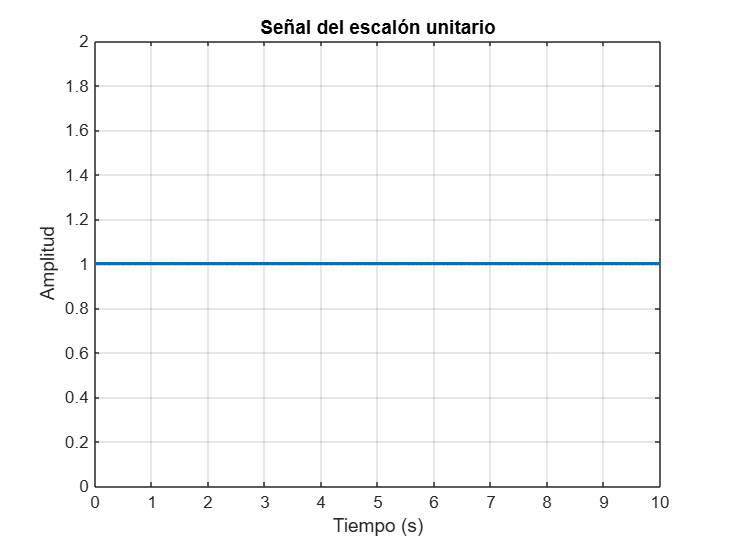

% Definición del tiempo 
Ts = 0.01; 
t = 0:Ts:10; 

% Señal de escalón unitario 
u = ones(size(t)); 
figure;
plot(t, u, 'LineWidth', 2); 
title('Señal del escalón unitario'); 
xlabel('Tiempo (s)'); 
ylabel('Amplitud'); 
grid on;

- **Simulación 2: **Representación gráfica del escalón unitario en un sistema discreto.

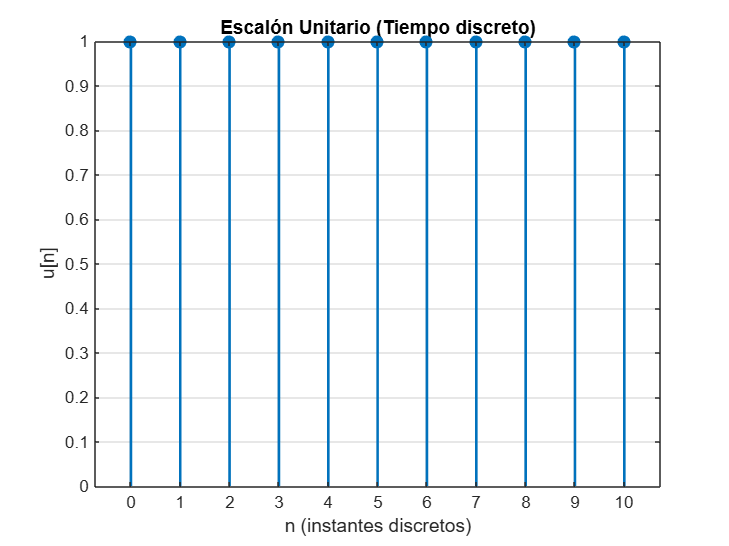

% Parámetros del tiempo discreto
n = 0:10; % Vector de instantes discretos (0 a 10)

% Escalón unitario
u = ones(size(n)); % La señal es 1 para n >= 0

% Graficar Escalón Unitario
figure;
stem(n, u, 'filled', 'LineWidth', 1.5); % Gráfica discreta
title('Escalón Unitario (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('u[n]');
grid on;

# **Rampa.**

- **Definición:**

La función rampa, denotada como $r\left(t\right)$, es una función definida como:


$$r\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \textrm{si}\;t<0\\
t & \textrm{si}\;t\ge 0
\end{array}\right.$$


Representa un incremento lineal en el tiempo a partir de $t=0\ldotp$

- **Demostración matemática:**

En sistemas continuos, su **transformada de Laplace** es:


$$R\left(s\right)=\int_0^{\infty } t\cdot e^{-\textrm{st}} \textrm{dt}$$


Esta es una integral por partes, donde:

- Sea $u=t\;\mathrm{y}\;\textrm{du}=e^{-\textrm{st}} \textrm{dt}$

- Entonces, $\textrm{du}=\textrm{dt}\;\mathrm{y}\;v=-\frac{1}{s}e^{-\textrm{st}}$

Por partes: 


$$R\left(s\right)=\left\lbrack -\frac{t}{s}e^{-\textrm{st}} \right\rbrack +\int_0^{\infty } \frac{1}{s}e^{-\textrm{st}} \textrm{dt}$$


- El primer término se evalúa como $0$ porque ${\textrm{te}}^{-\textrm{st}} \longrightarrow 0\;\textrm{cuando}\;t\longrightarrow \infty \;\mathrm{y}\;s>0$

La integral resultante es: 


$$\int_0^{\infty } \frac{1}{s}e^{-\textrm{st}} \textrm{dt}=\frac{1}{s}\cdot \frac{1}{s}$$


Entonces:


$$\mathit{\mathbf{R}}\left(\mathit{\mathbf{s}}\right)=\frac{1}{{\mathit{\mathbf{s}}}^2 }$$


En sistemas digitales, su **transformada Z** es:

Para la rampa discreta, $r\left\lbrack k\right\rbrack =k\;\textrm{para}\;k\ge 0,$ usando la definición de la transformada Z:


$$\begin{array}{l}
R\left(z\right)=\sum_{k=0}^{\infty } r\left\lbrack k\right\rbrack \cdot z^{-k} \\
R\left(z\right)=\sum_{k=0}^{\infty } k\cdot z^{-k} 
\end{array}$$


Para resolver, se utiliza una propiedad derivada de la serie geométrica básica:


$$\sum_{k=0}^{\infty } x^k =\frac{1}{1-x}\;\textrm{para}\;\left|x\right|<1$$


Se toma la derivada con respecto a $x$ en ambos lados para introducir el término de $k$:


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)$$


Resolviendo:

- En la sección izquierda: 


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1}$$


- En la sección derecha: 


$$\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)=\frac{1}{{\left(1-x\right)}^2 }$$


Por lo tanto:


$$\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1} =\frac{1}{{\left(1-x\right)}^2 }$$


Se multiplica por $x$ para ajustar la potencia: 


$$\sum_{K=0}^{\infty } {\textrm{kx}}^k =\frac{x}{{\left(1-x\right)}^2 }$$


En la transformada Z, se obtiene $x=z^{-1} \ldotp$ Sustituyendo:


$$\sum_{K=0}^{\infty } {\textrm{kz}}^{-k} =\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Simplificando:


$$R\left(z\right)=\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Multiplicar el numerador y denominador por $z^2$ para eliminar los términos $z^{-1}$:


$$\mathit{\mathbf{R}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{{\left(\mathit{\mathbf{z}}-1\right)}^2 }$$


- **Simulación 1: **Representación gráfica de la rampa en un sistema continuo.

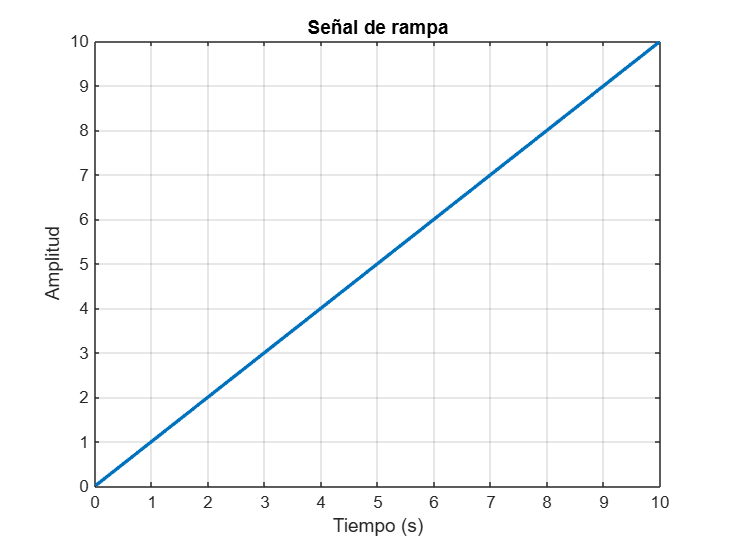

% Definición del tiempo
Ts = 0.01; 
t = 0:Ts:10; 

% Señal de rampa
r = t;
figure;
plot(t, r, 'LineWidth', 2);
title('Señal de rampa');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

- **Simulación 2: **Representación gráfica de la rampa en un sistema discreto.

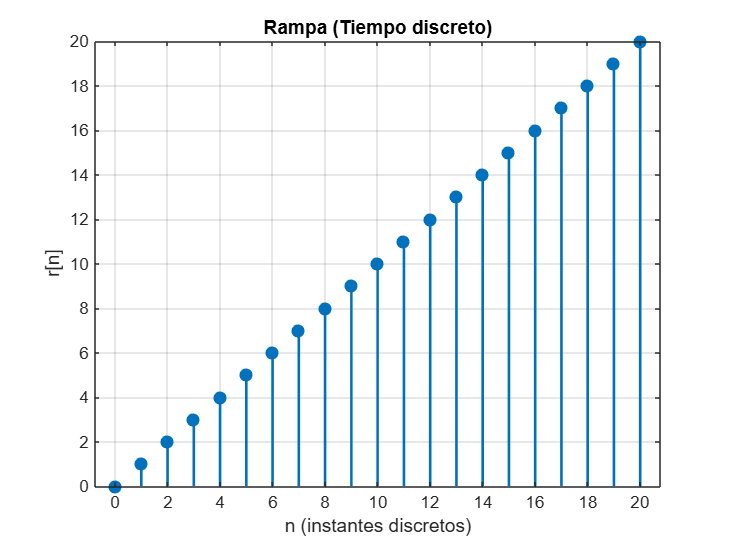

% Parámetros del tiempo discreto
n = 0:20; % Vector de instantes discretos (0 a 20)
% Rampa
r = n; % La rampa toma el valor del índice

% Graficar la Rampa
figure;
stem(n, r, 'filled', 'LineWidth', 1.5); % Gráfica discreta
title('Rampa (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('r[n]');
grid on;

- **Interpretación de resultados para el análisis de sistemas de control.**

**Ejemplo:** Respuesta de un sistema digital.

Se define un sistema digital con la función de transferencia:


$$H\left(z\right)=\frac{0\ldotp 1}{1-0\ldotp 9z^{-1} }$$


donde $T_s =0\ldotp 01$

- **Respuesta en el tiempo continuo:**

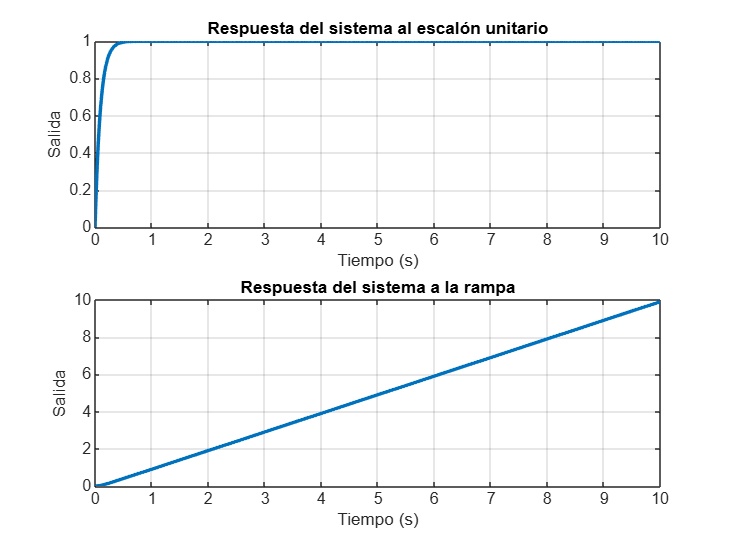

% Definir sistema digital
Ts = 0.01; % Tiempo de muestreo
t = 0:Ts:10; % Vector de tiempo continuo
num = [0.1]; 
den = [1 -0.9]; 
sys = tf(num, den, Ts); % Sistema digital

% Señal de entrada: Escalón
u = ones(size(t))';

% Respuesta al escalón
y_step = lsim(sys, u, t);

% Señal de entrada: Rampa
r = t'; 

% Respuesta a la rampa
y_ramp = lsim(sys, r, t);

% Graficar respuestas
figure;

% Respuesta al escalón
subplot(2,1,1);
plot(t, y_step, 'LineWidth', 2);
title('Respuesta del sistema al escalón unitario');
xlabel('Tiempo (s)');
ylabel('Salida');
grid on;

% Respuesta a la rampa
subplot(2,1,2);
plot(t, y_ramp, 'LineWidth', 2);
title('Respuesta del sistema a la rampa');
xlabel('Tiempo (s)');
ylabel('Salida');
grid on;

**Respuesta al escalón unitario:**

- Representa cómo el sistema reacciona ante una entrada constante.

- Se Observan características como el tiempo de subida, asentamiento y estabilidad.

**Respuesta a la rampa:**

- Evalúa el seguimiento de entradas lineales.

- Permite medir errores dinámicos.

- **Respuesta en el tiempo discreto.**

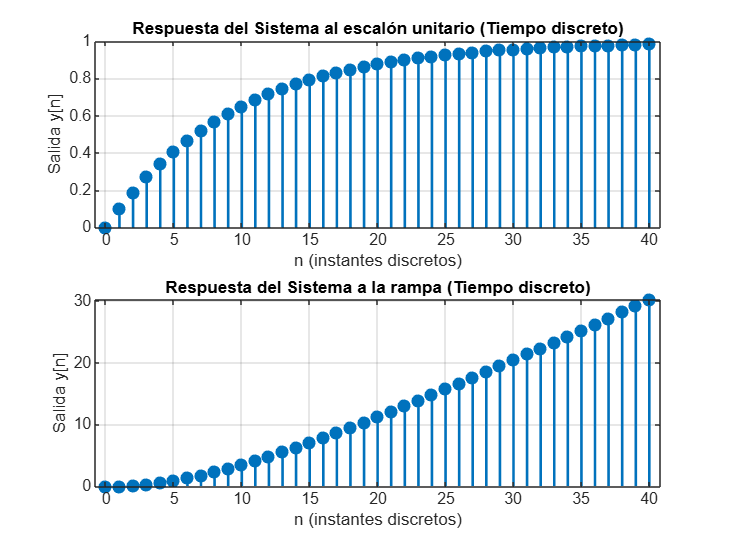

% Definir parámetros del sistema digital
Ts = 0.1; % Tiempo de muestreo
n = 0:1:40; % Instantes de tiempo discreto (40 muestras)
t = n * Ts; % Tiempo equivalente en segundos
num = [0.1];
den = [1 -0.9];
sys = tf(num, den, Ts); % Definir sistema en tiempo discreto

% Señal de entrada: Escalón unitario
u = ones(size(n))';

% Respuesta del sistema al escalón
y_step = lsim(sys, u, t);

% Señal de entrada: Rampa
r = n'; 

% Respuesta del sistema a la rampa
y_ramp = lsim(sys, r, t);

% Graficar resultados en tiempo discreto
figure;

% Gráfico de la respuesta al escalón
subplot(2,1,1);
stem(n, y_step, 'filled', 'LineWidth', 1.5); % Gráfica en tiempo discreto
title('Respuesta del Sistema al escalón unitario (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('Salida y[n]');
grid on;

% Gráfico de la respuesta a la rampa
subplot(2,1,2);
stem(n, y_ramp, 'filled', 'LineWidth', 1.5); % Gráfica en tiempo discreto
title('Respuesta del Sistema a la rampa (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('Salida y[n]');
grid on;

**Respuesta al escalón unitario:**

- Representa cómo el sistema digital responde a una entrada constante, evaluando su comportamiento en instantes específicos de tiempo.

- Permite observar características como estabilidad, convergencia, y posibles oscilaciones en el dominio discreto.

**Respuesta a la rampa:**

- Evalúa el seguimiento de señales con pendiente constante en sistemas digitales.

- Permite analizar errores de seguimiento en tiempo discreto, afectados por el tiempo de muestreo $\left(T_s \right)$ y la dinámica del sistema.